# Data Preparation

clc
clear all
close all
rng(0)

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m     = size(A, 2);
N     = null(A, 'rational');
pinvN = pinv(N);

# Load data from random data generator

buffer_name       = 'train10k';
buffer_train      = load(strcat(['ImitationLearning\TrainingData\Data\', buffer_name, '.mat']), 'buffer').buffer;
buffer_validation = load('ImitationLearning\TrainingData\Data\validation.mat', 'buffer').buffer;

buffer_train

buffer_train = struct with fields:
    X: [22×10000 double]
    Y: [5×10000 double]

buffer_validation

buffer_validation = struct with fields:
    X: [22×1000 double]
    Y: [5×1000 double]


size(buffer_train.X)

ans =           22       10000



buffer = struct();
buffer.X = [buffer_train.X, buffer_validation.X];
buffer.Y = [buffer_train.Y, buffer_validation.Y];

X = buffer.X;
Y = buffer.Y;

Nsamples = size(X, 2)

Nsamples = 11000

Ninputs = size(X, 1)

Ninputs = 22

Noutputs = size(Y, 1)

Noutputs = 5

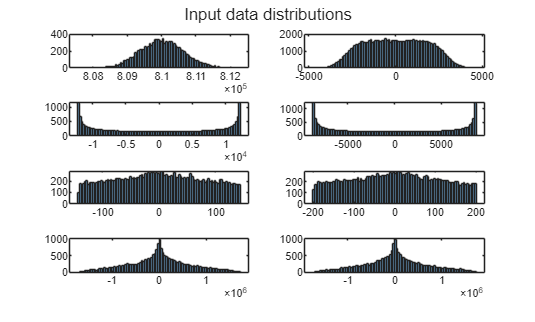


figure
subplot(4, 2, 1)
histogram(X(1, :), 100) % mean(Ec)
subplot(4, 2, 2)
histogram(X(2:10, :), 100) % Ec-mean(Ec)
subplot(4, 2, 3)
histogram(X(11:12, :), 100) % vxac, vxbc
subplot(4, 2, 4)
histogram(X(13:14, :), 100) % vyac, vybc
subplot(4, 2, 5)
histogram(X(15:16, :), 100) % ixa, ixb
subplot(4, 2, 6)
histogram(X(17:18, :), 100) % iya, iyb
subplot(4, 2, 7)
histogram(X(19:20, :), 100) % px1, px2
subplot(4, 2, 8)
histogram(X(21:22, :), 100) % py1, py1
sgtitle('Input data distributions')

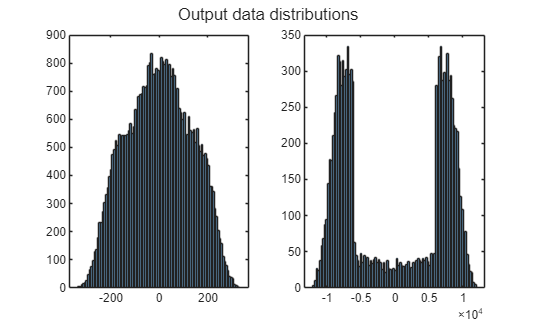


figure
subplot(1, 2, 1)
histogram(Y(1:4, :), 100)
subplot(1, 2, 2)
histogram(Y(5, :), 100)
sgtitle('Output data distributions')

Absolute maximum L.I. circulating and basic currents (assuming ie_ref_max~ie_max)

ixa = X(15, :);
ixb = X(16, :);
ixc = -(ixa + ixb);
iya = X(17, :);
iyb = X(18, :);
iyc = -(iya + iyb);

ixy = [ixa; ixb; ixc; iya; iyb; iyc];
iB = pinvA * ixy;
max(abs(iB(:)))

ans = 114.0174


ie = Y(1:4, :);
ie_max = max(abs(ie(:)))

ie_max = 335.3915

Input/outputs limits

Ax = 7000;
Ay = 5000;
[ix_max, iy_max, is_max, vo_max, vB_max, VCdiff] = max_values(Ax, Ay)

ix_max = 142.8571

iy_max = 200

is_max = 228.5714

vo_max = 6000

vB_max = 12000

VCdiff = 0.0020

Csm = 20e-3;
Nsm = 4;
C = Csm / Nsm

C = 0.0050

vc_mean_ref = vB_max + vo_max

vc_mean_ref = 18000


Emean = C/2 * (vc_mean_ref)^2      *1.1;            % Capacitor mean energy
Ediff = Emean * ((1+2*VCdiff)^2-1)     *ones(9, 1); % Capacitor energy deviation
VX = Ax                            *1.1*ones(3, 1); % Input voltage
VY = Ay                            *1.1*ones(3, 1); % Output voltage
IX = ix_max                        *1.1*ones(3, 1); % Input current
IY = iy_max                        *1.1*ones(3, 1); % Output current

IE = is_max                        *2*ones(4, 1);   % L.I. circulating currents
VO = vo_max;                                        % Common mode voltage

% Xmax = [Emean; E; VX; VY; IX; IY]

VX = sqrt(3) * VX(1:2);
VY = sqrt(3) * VY(1:2);
IX = IX(1:2);
IY = IY(1:2);
PX = VX .* IX /1.1;
PY = VY .* IY /1.1;

Xmax = [Emean; Ediff; VX; VY; IX; IY; PX; PY]

Xmax = 1.0e+06 *

    0.8910
    0.0071
    0.0071
    0.0071
    0.0071
    0.0071
    0.0071
    0.0071
    0.0071
    0.0071
    0.0133
    0.0133
    0.0095
    0.0095
    0.0002


Ymax = [IE; VO]

Ymax = 1.0e+03 *

    0.4571
    0.4571
    0.4571
    0.4571
    6.0000


# Preprocessing

Input/output sizes

size(X)

ans =           22       11000


size(Y)

ans =            5       11000


Normalization

X = X ./ Xmax;
Y = Y ./ Ymax;

Training/validation split

X_tr  = buffer_train.X ./ Xmax;
Y_tr  = buffer_train.Y ./ Ymax;
X_val = buffer_validation.X ./ Xmax;
Y_val = buffer_validation.Y ./ Ymax;

Data augmentation with white noise

% X_tr = [X_tr, X_tr+0.01*randn(size(X_tr))]
% Y_tr = [Y_tr, Y_tr]

Transform to dlarray

dlX     = dlarray(X, 'CB');
dlY     = dlarray(Y, 'CB');
dlX_tr  = dlarray(X_tr, 'CB');
dlY_tr  = dlarray(Y_tr, 'CB');
dlX_val = dlarray(X_val, 'CB');
dlY_val = dlarray(Y_val, 'CB');
dsX_tr  = arrayDatastore(dlX_tr, 'IterationDimension', 2);
dsY_tr  = arrayDatastore(dlY_tr, 'IterationDimension', 2);
dsXY_tr = combine(dsX_tr, dsY_tr);

# Exploratory data analysis

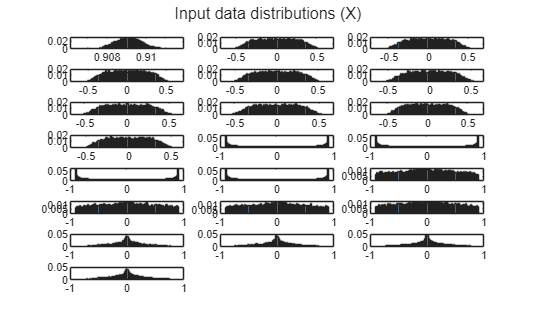

n_cols = 3;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if or(min(X(idx, :))<-1, max(X(idx, :))>1)
        histogram(X(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100, 'Normalization', 'probability');
    end
    % title(['X', num2str(idx)]);
    % ylabel('Freq');
end
sgtitle('Input data distributions (X)')

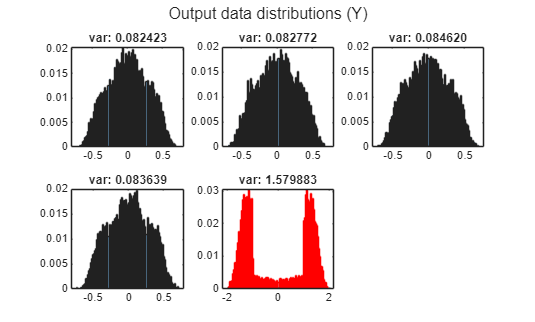


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if or(min(Y(idx, :))<-1, max(Y(idx, :))>1)
        histogram(Y(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100, 'Normalization', 'probability')
    end
    title(sprintf('var: %f', var(Y(idx, :))))
end
sgtitle('Output data distributions (Y)')

# Dimensionality reduction for state space visualization

## PCA

Input

% [coeff, score, latent] = pca(X');
% 
% figure
% subplot(1, 2 ,1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA X')

Output

% [coeff, score, latent] = pca(Y');
% 
% figure
% subplot(1, 2, 1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA Y')

## Clustering

% n_clusters = 5; % Número de clusters
% epsilon = 0.1;  % Radio máximo para DBSCAN
% minPts = 5;     % Mínimo número de puntos para DBSCAN
% 
% % K-means
% [idx_kmeans, C_kmeans] = kmeans(Y', n_clusters, 'Replicates', 10);
% 
% % DBSCAN
% idx_dbscan = dbscan(Y', epsilon, minPts);
% 
% % GMM
% gmm = fitgmdist(Y', n_clusters, 'RegularizationValue', 1e-5);
% idx_gmm = cluster(gmm, Y');
% 
% % PCA
% num_dims = 3;
% [coeff, score, latent] = pca(Y');
% X_reduced = score(:, 1:num_dims);
% 
% figure
% 
% % K-means
% subplot(1, 3, 1)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
% title('K-means'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % DBSCAN
% subplot(1, 3, 2)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
% title('DBSCAN'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % GMM
% subplot(1, 3, 3)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
% title('GMM'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% sgtitle('Clustering in Original Space');

## UMAP

% pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')
% system('pip install umap-learn')

2D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter(Xumap(:, 1), Xumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); grid on;
% 
% subplot(1, 2, 2);
% scatter(Yumap(:, 1), Yumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); grid on;

3D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=3)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter3(Xumap(:, 1), Xumap(:, 2), Xumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;
% 
% subplot(1, 2, 2);
% scatter3(Yumap(:, 1), Yumap(:, 2), Yumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;